## Tratamento inicial dos dados

Zerar workspace

clear;

Os dados originais (CSV) devem ter sido tratados previamente (editar a hora para o formato YYYY-MM-DD hh:mm:ss, adicionar linha de cabeçalho, verificar numero de colunas)

Importar CSV dos dados

node1 = readtable('logs/csv/coleta02_20170131_20170207/1/WMLOGB_edited.CSV');
node2 = readtable('logs/csv/coleta02_20170131_20170207/2/WMLOGB_edited.CSV');
node3 = readtable('logs/csv/coleta02_20170131_20170207/3/WMLOGB_edited.CSV');
node4 = readtable('logs/csv/coleta02_20170131_20170207/4/WMLOGB_edited.CSV');

Ajustando dados do sensor 03 do nó 4 (multiplicando por -1 para tornar os valores positivos)

node4.sensor03value = node4.sensor03value * -1;

**FIXME**: muitas leituras do sensor 03 não foram feitas/armazenadas. Testar gerar o valor utilizando mediana ou outro método

% desabilitado para usar apenas os dados coletados
% calcular novo valor médio ignorando os dados nulos
% node4.sensor03value = median(node4{1:end,53:74},2,'omitnan');

Converter tabelas em timetables

node1 = table2timetable(node1);
node2 = table2timetable(node2);
node3 = table2timetable(node3);
node4 = table2timetable(node4);

Conversão dos dados dos sensores de Ohm para cbar/kPa (utilizando a formula que leva em consideração a temperatura do solo)

*Detalhe: a temperatura utilizada não é do solo, mas do sensor RTC*

% wmlog_node1.sensor01cbar = (3.213*(wmlog_node1.sensor01value./1000)+4.093)./(1-0.009733*(wmlog_node1.sensor01value./1000)-0.01205*wmlog_node1.temperature)
% wmlog_node1.sensor02cbar = (3.213*(wmlog_node1.sensor02value./1000)+4.093)./(1-0.009733*(wmlog_node1.sensor02value./1000)-0.01205*wmlog_node1.temperature)
% wmlog_node1.sensor03cbar = (3.213*(wmlog_node1.sensor03value./1000)+4.093)./(1-0.009733*(wmlog_node1.sensor03value./1000)-0.01205*wmlog_node1.temperature)

Conversão dos dados dos sensores de Ohm para cbar/kPa (utilizanda a fórmula básica de conversão da irrometer)

node1{:,3:end} = (node1{:,3:end}-550)./137.5;
node2{:,3:end} = (node2{:,3:end}-550)./137.5;
node3{:,3:end} = (node3{:,3:end}-550)./137.5;
node4{2:end,3:end} = (node4{2:end,3:end}-550)./137.5; % ignorando a primeira linha, que é de 0

Determinar período de tempo a ser utilizado e filtrar tabelas

%range = timerange('2017-01-31', '2017-02-07');
%node1 = node1(range,:);
%node2 = node2(range,:);
%node4 = node4(range,:);

**FIXME**: ajustes de escala (sensor de 15cm dos nós 1 e 2 estão em uma ordem de grandeza maior, não sei o motivo)

% node1.sensor01cbar = node1.sensor01cbar/100;
% node2.sensor01cbar = node2.sensor01cbar/100;
node1{:,3:26} = node1{:,3:26}/100;
node2{:,3:26} = node2{:,3:26}/100;

**FIXME: verificar ****se a redução a seguir é mesmo necessária**

Segundo a documentação dos sensores watermark irrometer, eles foram calibrados para funcionar a 70ºF. A cada grau F acima de 70 é necessário reduzir a leitura em 1%

Considerando o solo a 32ºC (89.6ºF)

soil_temp = 89.6;
sensor_adjustment = (100 - (soil_temp - 70))/100;

node1{:,3:end} = node1{:,3:end} * sensor_adjustment;
node2{:,3:end} = node2{:,3:end} * sensor_adjustment;
node3{:,3:end} = node3{:,3:end} * sensor_adjustment;
node4{2:end,3:end} = node4{2:end,3:end} * sensor_adjustment; % a primeira linha é de 0, pois os dados nao foram coletados

AJUSTE TEMPORÁRIO: converter outliers do nó 3 em NaN

% node3.sensor02cbar(1) = NaN;
% node3.sensor02cbar(2) = NaN;
% node3.sensor02cbar(23) = NaN;
% node3.sensor02cbar(24) = NaN;
% node3.sensor02cbar(25) = NaN;
% node3.sensor02cbar(26) = NaN;

Identificar e remover outliers

% FIXME: decidir entre 0 e NaN

% removendo valores acima de 200
% outliers = node1{:,3:74} > 200;
% node1{:,3:74}(outliers) = NaN;  % usar 0 ou NaN
% outliers = node1{:,3:74} < 0;
% node1{:,3:74}(outliers) = NaN;  % usar 0 ou NaN
% convertendo nan em 0
% nans = isnan(node1{:,3:74});
% node1{:,3:74}(nans) = 0;

% removendo valores acima de 200
% outliers = node2{:,3:74} > 200;
% node2{:,3:74}(outliers) = NaN;
% outliers = node2{:,3:74} < 0;
% node2{:,3:74}(outliers) = NaN;
% convertendo nan em 0
% nans = isnan(node2{:,3:74});
% node2{:,3:74}(nans) = 0;

% removendo valores acima de 200
% outliers = node3{:,3:74} > 200;
% node3{:,3:74}(outliers) = NaN;
% outliers = node3{:,3:74} < 0;
% node3{:,3:74}(outliers) = NaN;
% convertendo nan em 0
% nans = isnan(node3{:,3:74});
% node3{:,3:74}(nans) = 0;

% removendo valores acima de 200
% outliers = node4{:,3:74} > 200;
% node4{:,3:74}(outliers) = NaN;
% outliers = node4{:,3:74} < 0;
% node4{:,3:74}(outliers) = NaN;
% convertendo nan em 0
% nans = isnan(node4{:,3:74});
% node4{:,3:74}(nans) = 0;

## Configuração de plotagem dos gráficos

Determinar variáveis para plotar linhas de indicação de umidade do solo

DateStrings = {'2017-01-31';'2017-02-08'};
t = datetime(DateStrings,'InputFormat','yyyy-MM-dd');

Informação de saturação do solo:

- 0 a 10: solo saturado

- 10 a 30: solo adequadamente umido (exceto areia fina)

- 30 a 60: necessita rega

- 60 a 100: necessita rega (barro pesado)

- 100 a 200: perigosamente seco

## Cálculo: Nova média

Calculando novas médias para todos os nós e sensores

node1.sensor01mean = mean(node1{1:end,5:26},2,'omitnan');
% node1.sensor01mean = (mean(node1{1:end,5:15},2,'omitnan') + mean(node1{1:end,16:26},2,'omitnan') ) / 2;
node1.sensor02mean = mean(node1{1:end,29:50},2,'omitnan');
node1.sensor03mean = mean(node1{1:end,53:74},2,'omitnan');

node2.sensor01mean = mean(node2{1:end,5:26},2,'omitnan');
node2.sensor02mean = mean(node2{1:end,29:50},2,'omitnan');
node2.sensor03mean = mean(node2{1:end,53:74},2,'omitnan');

node3.sensor01mean = mean(node3{1:end,5:26},2,'omitnan');
node3.sensor02mean = mean(node3{1:end,29:50},2,'omitnan');
node3.sensor03mean = mean(node3{1:end,53:74},2,'omitnan');

node4.sensor01mean = mean(node4{1:end,5:26},2,'omitnan');
node4.sensor02mean = mean(node4{1:end,29:50},2,'omitnan');
node4.sensor03mean = mean(node4{1:end,53:74},2,'omitnan');

## Cálculo: Mediana

Calculando medianas para todos os nós e sensores

node1.sensor01median = median(node1{1:end,5:26},2,'omitnan');
node1.sensor02median = median(node1{1:end,29:50},2,'omitnan');
node1.sensor03median = median(node1{1:end,53:74},2,'omitnan');

node2.sensor01median = median(node2{1:end,5:26},2,'omitnan');
node2.sensor02median = median(node2{1:end,29:50},2,'omitnan');
node2.sensor03median = median(node2{1:end,53:74},2,'omitnan');

node3.sensor01median = median(node3{1:end,5:26},2,'omitnan');
node3.sensor02median = median(node3{1:end,29:50},2,'omitnan');
node3.sensor03median = median(node3{1:end,53:74},2,'omitnan');

node4.sensor01median = median(node4{1:end,5:26},2,'omitnan');
node4.sensor02median = median(node4{1:end,29:50},2,'omitnan');
node4.sensor03median = median(node4{1:end,53:74},2,'omitnan');

## Gráficos: Média original

Plotar dados dos sensores de 15cm

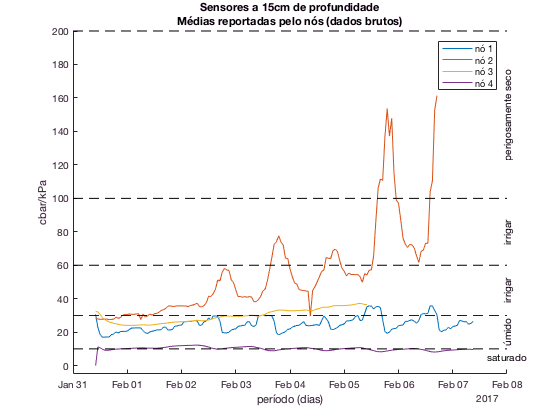

plotar_sensores(node1.time,node2.time,node3.time,node4.time,...
    node1.sensor01value,node2.sensor01value,node3.sensor01value,node4.sensor01value,...
    '15cm','media_original');

Plotar dados dos sensores de 45cm

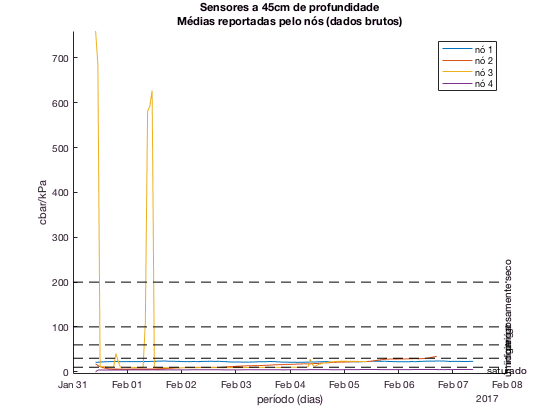

plotar_sensores(node1.time,node2.time,node3.time,node4.time,...
    node1.sensor02value,node2.sensor02value,node3.sensor02value,node4.sensor02value,...
    '45cm','media_original');

Plotar dados dos sensores de 75cm

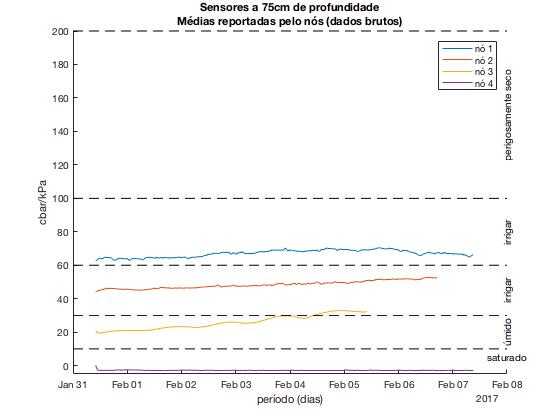

plotar_sensores(node1.time,node2.time,node3.time,node4.time,...
    node1.sensor03value,node2.sensor03value,node3.sensor03value,node4.sensor03value,...
    '75cm','media_original');

## Gráficos: Média nova

Plotar dados dos sensores de 15cm

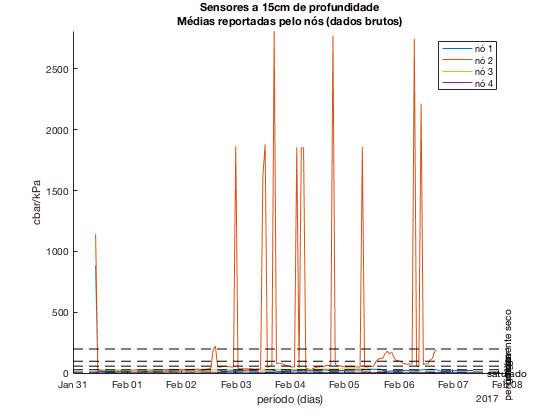

plotar_sensores(node1.time,node2.time,node3.time,node4.time,...
    node1.sensor01mean,node2.sensor01mean,node3.sensor01mean,node4.sensor01mean,...
    '15cm','media_nova');

Plotar dados dos sensores de 45cm

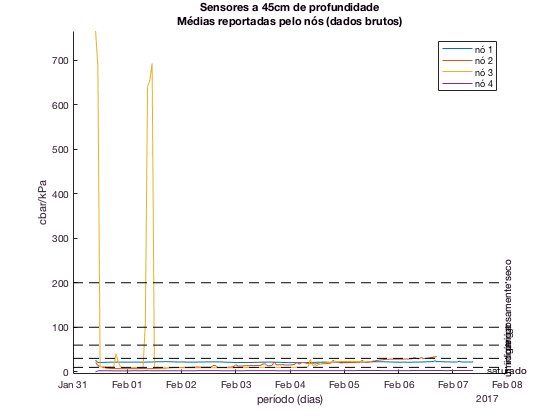

plotar_sensores(node1.time,node2.time,node3.time,node4.time,...
    node1.sensor02mean,node2.sensor02mean,node3.sensor02mean,node4.sensor02mean,...
    '45cm','media_nova');

Plotar dados dos sensores de 75cm

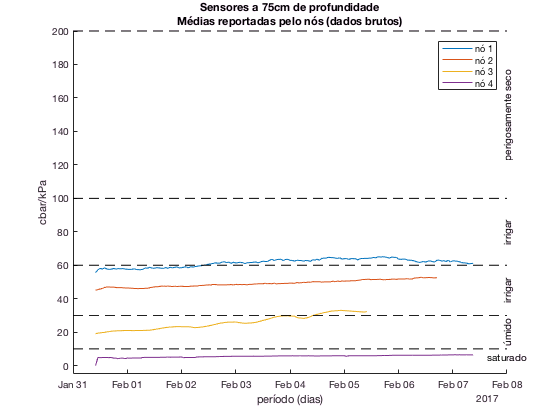

plotar_sensores(node1.time,node2.time,node3.time,node4.time,...
    node1.sensor03mean,node2.sensor03mean,node3.sensor03mean,node4.sensor03mean,...
    '75cm','media_nova');

## Gráficos: Mediana

Plotar dados dos sensores de 15cm

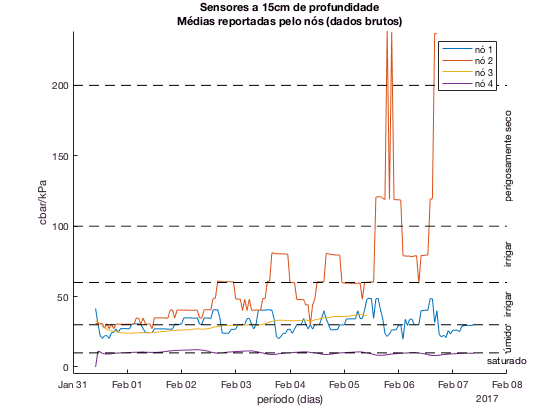

plotar_sensores(node1.time,node2.time,node3.time,node4.time,...
    node1.sensor01median,node2.sensor01median,node3.sensor01median,node4.sensor01median,...
    '15cm','mediana');

Plotar dados dos sensores de 45cm

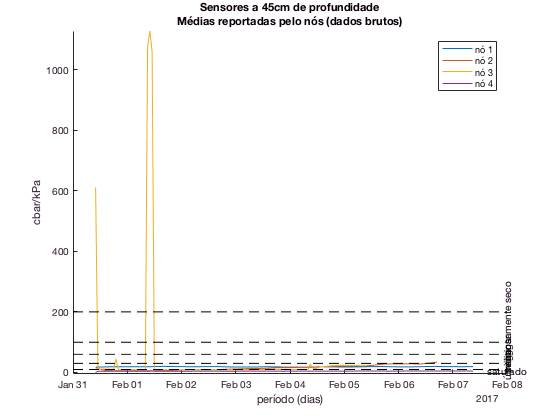

plotar_sensores(node1.time,node2.time,node3.time,node4.time,...
    node1.sensor02median,node2.sensor02median,node3.sensor02median,node4.sensor02median,...
    '45cm','mediana');

Plotar dados dos sensores de 75cm

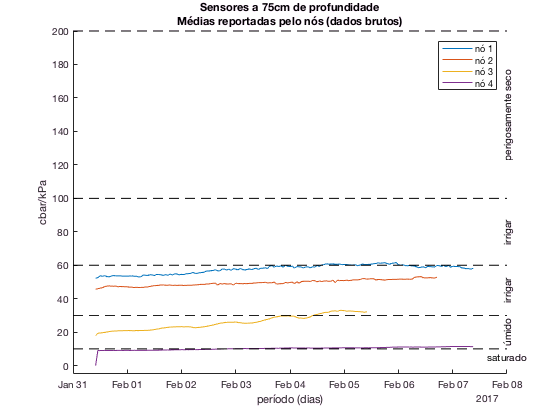

plotar_sensores(node1.time,node2.time,node3.time,node4.time,...
    node1.sensor03median,node2.sensor03median,node3.sensor03median,node4.sensor03median,...
    '75cm','mediana');

# Fusão: média, mediana, média móvel e kalman

## Parâmetros

Biases #FIXME: falta deteminar o bias de cada um dos sensores

% bias (constant inaccuracy; or mean value of the noise) in each of the sensors.
% As you can see, when sensors are biased in different directions, sensor fusion
% can provide a closer approximation to the “true” state of the system than you
% can get with a single sensor alone
BIAS1 = +1;
BIAS2 = -1;
BIAS3 = 0;
BIAS4 = 0;

Covariância do ruídos das medições *#FIXME: falta atualizar esses valores. Utilizando os valores do exemplo.*

% for our single-sensor example, we defined 'r' as the variance of the observation
% noise signal 'vk'; that is, how much it varies around its mean (average) value.
% For a system with more than two sensors, 'R' is a matrix containing the 
% covariance between each pair of sensors

% Let's say that we've observed both our thermometers under climate-controlled
% conditions of steady temperature, and observed that their values fluctuate by
% an average of 0.8 degrees; i.e., the standard deviation of their readings is
% 0.8, making the variance 0.8 * 0.8 = 0.64
% R = [R1 0 0 0
%      0 R2 0 0
%      0 0 R3 0
%      0 0 0 R4]
R1 = 0.64;
R2 = 0.64;
R3 = 0.64;
R4 = 0.64;

Covariância do ruído do processo *#FIXME: falta** atualizar esse valor. Utilizando o valor do exemplo.*

Q = .005;

Estado do modelo de transição. Como o estado anterior não é conhecido então se inicia em 1

% we'll assume we have no knowledge of the state-transition model
% ('A' matrix) and so have to rely only on the sensor values
A = 1;

Modelo de observação (qual o grau de influencia dos dados do sensores na estimativa dos dados. Max: 1)

% We'll assume that both sensors contribute equally to our temperature estimation,
% so our CC matrix is just a pair of 1's
C1 = 1;
C2 = 1;
C3 = 1;
C4 = 1;

## Fusão: média

Média normal dos dados dos sensores

sensor1mean = [node1.sensor01mean node2.sensor01mean node3.sensor01mean node4.sensor01mean];
sensor2mean = [node1.sensor02mean node2.sensor02mean node3.sensor02mean node4.sensor02mean];
sensor3mean = [node1.sensor03mean node2.sensor03mean node3.sensor03mean node4.sensor03mean];
% gerando a transposta dos dados para facilitar a manipulação dos dados e uso dos filtros (que trabalham com colunas)
sensor1mean = sensor1mean';
sensor2mean = sensor2mean';
sensor3mean = sensor3mean';
sensor1fusedMean = mean(sensor1mean, 'omitnan');
sensor2fusedMean = mean(sensor2mean, 'omitnan');
sensor3fusedMean = mean(sensor3mean, 'omitnan');

## Fusão: média móvel

Média móvel (janela de 6 horas e 12 horas)

sensor1fusedMAF6 = movmean(sensor1fusedMean,6);
sensor1fusedMAF12 = movmean(sensor1fusedMean,12);

## Fusão: mediana

sensor1median = [node1.sensor01median node2.sensor01median node3.sensor01median node4.sensor01median];
% gerando a transposta dos dados para facilitar a manipulação dos dados e uso dos filtros (que trabalham com colunas)
sensor1median = sensor1median';
sensor1fusedMedian = median(sensor1median, 'omitnan');

## Filtro de Kalman

% FIXME: ajuste manual necessário para evitar problemas com filtro de kalman (ele não gosta de NaN)
sensor2mean(3,24:26) = 0;

% 1 sensor
sensor1fusedKAF1 = kalman([sensor1mean(1,:)], A, [C1], [R1], Q);

% 2 sensores
sensor1fusedKAF2 = kalman([sensor1mean(1,:); sensor1mean(2,:)], A, [C1; C2], [R1 0; 0 R2], Q);

% 3 sensores
sensor1fusedKAF3 = kalman([sensor1mean(1,:); sensor1mean(2,:); sensor1mean(3,:)], A, [C1; C2; C3], [R1 0 0; 0 R2 0; 0 0 R3], Q);

% 4 sensores
% sensor1fusedKAF4 = kalman([sensor1mean(1,:); sensor1mean(2,:); sensor1mean(4,:)], A, [C1; C2; C3], [R1 0 0; 0 R2 0; 0 0 R3], Q);
sensor1fusedKAF4 = kalman([sensor1mean(1,:); sensor1mean(2,:); sensor1mean(3,:); sensor1mean(4,:)], A, [C1; C2; C3; C4], [R1 0 0 0; 0 R2 0 0; 0 0 R3 0; 0 0 0 R4], Q);
sensor2fusedKAF4 = kalman([sensor2mean(1,:); sensor2mean(2,:); sensor2mean(3,:); sensor2mean(4,:)], A, [C1; C2; C3; C4], [R1 0 0 0; 0 R2 0 0; 0 0 R3 0; 0 0 0 R4], Q);
sensor3fusedKAF4 = kalman([sensor3mean(1,:); sensor3mean(2,:); sensor3mean(3,:); sensor3mean(4,:)], A, [C1; C2; C3; C4], [R1 0 0 0; 0 R2 0 0; 0 0 R3 0; 0 0 0 R4], Q);

## Plotar gráficos

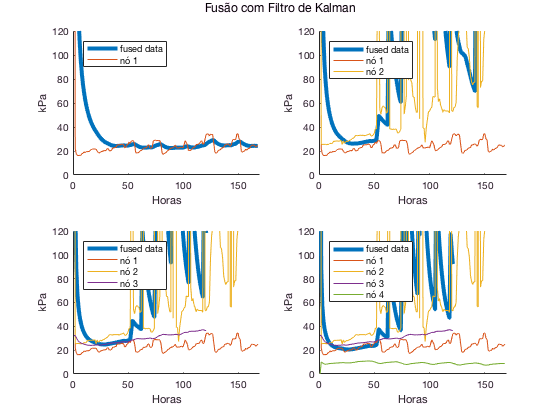

clf % clear current figure
kalmanSubplot = figure;
a = subplot(2,2,1);
hold on
plot(sensor1fusedKAF1,'DisplayName','fused data','LineWidth',4)
plot(node1.sensor01mean,'DisplayName','nó 1')
legend('show','Location','northwest')
ylabel('kPa')
xlabel('Horas')
xlim([0 170])
ylim([0 120])
% title(a,'1 nó')
hold off

b = subplot(2,2,2);
hold on
plot(sensor1fusedKAF2,'DisplayName','fused data','LineWidth',4)
plot(node1.sensor01mean,'DisplayName','nó 1')
plot(node2.sensor01mean,'DisplayName','nó 2')
legend('show','Location','northwest')
ylabel('kPa')
xlabel('Horas')
xlim([0 170])
ylim([0 120])
hold off

c = subplot(2,2,3);
hold on
plot(sensor1fusedKAF3,'DisplayName','fused data','LineWidth',4)
plot(node1.sensor01mean,'DisplayName','nó 1')
plot(node2.sensor01mean,'DisplayName','nó 2')
plot(node3.sensor01mean,'DisplayName','nó 3')
legend('show','Location','northwest')
ylabel('kPa')
xlabel('Horas')
xlim([0 170])
ylim([0 120])
hold off

d = subplot(2,2,4);
hold on
plot(sensor1fusedKAF4,'DisplayName','fused data','LineWidth',4)
plot(node1.sensor01mean,'DisplayName','nó 1')
plot(node2.sensor01mean,'DisplayName','nó 2')
plot(node3.sensor01mean,'DisplayName','nó 3')
plot(node4.sensor01mean,'DisplayName','nó 4')
legend('show','Location','northwest')
ylabel('kPa')
xlabel('Horas')
xlim([0 170])
ylim([0 120])
hold off

figtitle('Fusão com Filtro de Kalman');
saveas(kalmanSubplot,'graphs/sensores_15cm_kalman','jpg');

Plotar gráfico comparativo

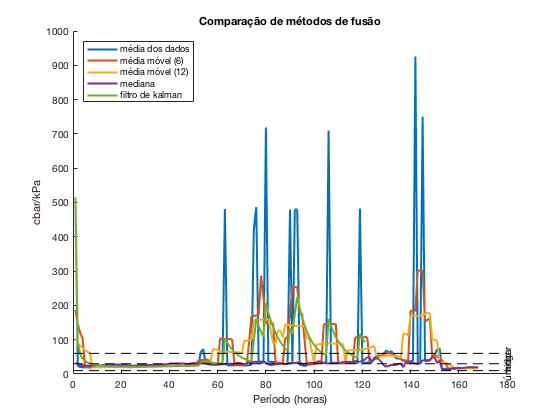

clf
fusionCompare = figure;
hold on
plot(sensor1fusedMean,'DisplayName','média dos dados','LineWidth',2);
plot(sensor1fusedMAF6,'DisplayName','média móvel (6)','LineWidth',2);
plot(sensor1fusedMAF12,'DisplayName','média móvel (12)','LineWidth',2);
plot(sensor1fusedMedian,'DisplayName','mediana','LineWidth',2);
plot(sensor1fusedKAF4,'DisplayName','filtro de kalman','LineWidth',2);
plot([0 180],[10 10], 'k--','HandleVisibility','off'); % 0 a 10: solo saturado
% saturado = text(180,5,'saturado','HorizontalAlignment','center');
% set(saturado,'rotation',90);
umido = text(180,20,'úmido','HorizontalAlignment','center');
set(umido,'rotation',90);
plot([0 180],[30 30], 'k--','HandleVisibility','off'); % 10 a 30: solo adequadamente umido (exceto areia fina)
irrigar1 = text(180,45,'irrigar','HorizontalAlignment','center');
set(irrigar1,'rotation',90);
plot([0 180],[60 60], 'k--','HandleVisibility','off'); % 30 a 60: necessita rega
% irrigar2 = text(180,80,'irrigar','HorizontalAlignment','center');
% set(irrigar2,'rotation',90);
% plot([100 100], 'k--','HandleVisibility','off'); % 60 a 100: necessita rega (barro pesado)
% seco = text(8,150,'perigosamente seco','HorizontalAlignment','center');
% set(seco,'rotation',90);
% plot([200 200], 'k--','HandleVisibility','off'); % 100 a 200: perigosamente seco
hold off
legend('Location','northwest')
ylabel('cbar/kPa')
xlabel('Período (horas)')
hold off

title('Comparação de métodos de fusão');
saveas(fusionCompare,'graphs/sensores_15cm_fusao_comparacao','jpg')

Plotar gráfico comparativo

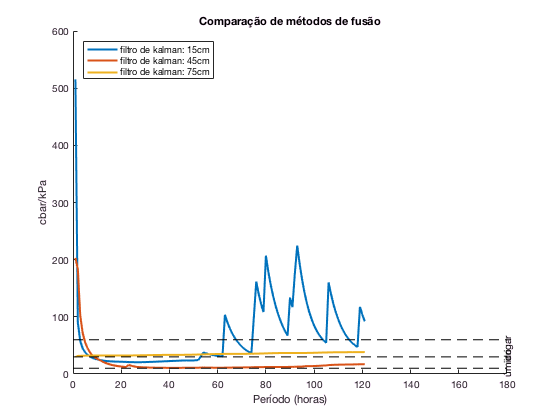

clf
fusionCompare = figure;
hold on
plot(sensor1fusedKAF4,'DisplayName','filtro de kalman: 15cm','LineWidth',2);
plot(sensor2fusedKAF4,'DisplayName','filtro de kalman: 45cm','LineWidth',2);
plot(sensor3fusedKAF4,'DisplayName','filtro de kalman: 75cm','LineWidth',2);
plot([0 180],[10 10], 'k--','HandleVisibility','off'); % 0 a 10: solo saturado
% saturado = text(180,5,'saturado','HorizontalAlignment','center');
% set(saturado,'rotation',90);
umido = text(180,20,'úmido','HorizontalAlignment','center');
set(umido,'rotation',90);
plot([0 180],[30 30], 'k--','HandleVisibility','off'); % 10 a 30: solo adequadamente umido (exceto areia fina)
irrigar1 = text(180,45,'irrigar','HorizontalAlignment','center');
set(irrigar1,'rotation',90);
plot([0 180],[60 60], 'k--','HandleVisibility','off'); % 30 a 60: necessita rega
% irrigar2 = text(180,80,'irrigar','HorizontalAlignment','center');
% set(irrigar2,'rotation',90);
% plot([100 100], 'k--','HandleVisibility','off'); % 60 a 100: necessita rega (barro pesado)
% seco = text(8,150,'perigosamente seco','HorizontalAlignment','center');
% set(seco,'rotation',90);
% plot([200 200], 'k--','HandleVisibility','off'); % 100 a 200: perigosamente seco
hold off
legend('Location','northwest')
ylabel('cbar/kPa')
xlabel('Período (horas)')
hold off

title('Comparação de métodos de fusão');
saveas(fusionCompare,'graphs/sensores_todos_fusao_kalman','jpg')

# Outros métodos p/ detectar outliers

## Transposta dos dados dos sensores

sensor1meanT = sensor1mean';

## Convertendo NaN para 0

Identificar e remover outliers

% convertendo nan em 0
nans = isnan(sensor1meanT);
sensor1meanT(nans) = 0;

## Modified Z-score

% FIXME: threshold (terceiro parâmetro) padrão é 3.5
% FIXME: distance (quarto parâmetro) indica se os dados possuem distribuição normal (0 - padrão) ou log-normal (1)
[MZscore MZmax MZoutlier MZoutnum] = mzscore(sensor1meanT,x_date,3.5,0);

% data (y value for plotting)
mzplot = []


mzplot =

     []



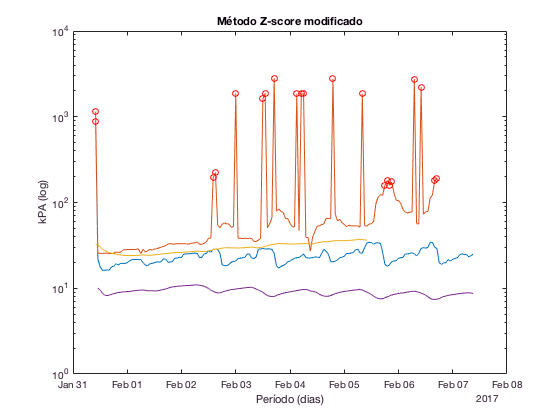

for i = 1:size(MZoutnum,1)
    mzplot = [mzplot; sensor1meanT(MZoutnum(i,1),MZoutnum(i,2))];
end

% time (x value for plotting)
MZtime = MZoutlier(:,1);
t = datetime(MZtime);

% plot
mzGraph = figure;
semilogy(node1.time,sensor1meanT)
hold on
semilogy(t,mzplot,'LineStyle','none','Marker','o','MarkerEdgeColor','red')
hold off
title('Método Z-score modificado');
xlabel('Período (dias)');
ylabel('kPA (log)');

## Modified box plot

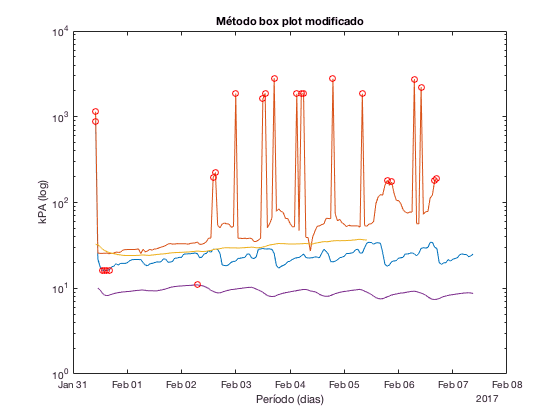

% FIXME: utilizando valor 1.8 para K (skewness), pois foi o que se mostrou mais válido para os dados.
% O valor padrão é 1.5. Falta descobrir qual maneira mais adequada/automatizada para determinar K

% artigo: Hubert, M., & Vandervieren, E. (2008). An adjusted boxplot for skewed distributions. Computational Statistics and Data Analysis, 52(12), 5186–5201. https://doi.org/10.1016/j.csda.2007.11.008

[boxQ1 boxQ3 boxMC boxOUT boxOUTnum] = adjboxplot(sensor1meanT,x_date,1.5);
% sensor1meanT(boxOUTnum(5,1),boxOUTnum(5,2));

% data (y value for plotting)
boxOUTplot = [];
for i = 1:size(boxOUTnum,1)
    boxOUTplot = [boxOUTplot; sensor1meanT(boxOUTnum(i,1),boxOUTnum(i,2))];
end

% time (x value for plotting)
boxOUTtime = boxOUT(:,1);
boxOUTtime = datetime(boxOUTtime);

% plot
adjboxplotGraph = figure;
semilogy(node1.time,sensor1meanT)
hold on
semilogy(boxOUTtime,boxOUTplot,'LineStyle','none','Marker','o','MarkerEdgeColor','red')
hold off
title('Método box plot modificado');
xlabel('Período (dias)');
ylabel('kPA (log)');

function plotar_sensores(y1,y2,y3,y4,x1,x2,x3,x4,depth,type)
    grafico = figure;
    hold on
    ylim([-5; Inf]);
    plot(y1,x1)
    plot(y2,x2)
    plot(y3,x3)
    plot(y4,x4)
    DateStrings = {'2017-01-31';'2017-02-08'};
    t = datetime(DateStrings,'InputFormat','yyyy-MM-dd');
    saturado = text(8,5,'saturado','HorizontalAlignment','center');
    % set(saturado,'rotation',90);
    plot(t,[10 10], 'k--','HandleVisibility','off'); % 0 a 10: solo saturado
    umido = text(8,20,'úmido','HorizontalAlignment','center');
    set(umido,'rotation',90);
    plot(t,[30 30], 'k--','HandleVisibility','off'); % 10 a 30: solo adequadamente umido (exceto areia fina)
    irrigar1 = text(8,45,'irrigar','HorizontalAlignment','center');
    set(irrigar1,'rotation',90);
    plot(t,[60 60], 'k--','HandleVisibility','off'); % 30 a 60: necessita rega
    irrigar2 = text(8,80,'irrigar','HorizontalAlignment','center');
    set(irrigar2,'rotation',90);
    plot(t,[100 100], 'k--','HandleVisibility','off'); % 60 a 100: necessita rega (barro pesado)
    seco = text(8,150,'perigosamente seco','HorizontalAlignment','center');
    set(seco,'rotation',90);
    plot(t,[200 200], 'k--','HandleVisibility','off'); % 100 a 200: perigosamente seco
    hold off
    legend('nó 1','nó 2','nó 3','nó 4')
    ylabel('cbar/kPa')
    xlabel('período (dias)')
    plottitle = sprintf('Sensores a %s de profundidade',depth);
    title({plottitle,'Médias reportadas pelo nós (dados brutos)'});
    filename = sprintf('graphs/sensores_%s_%s',depth,type);
    saveas(grafico,filename,'jpg')
    
%     function plotsigs(pos, sig1, sig2, sig1label)
% subplot(3,1,pos)
% hold on
% plot(sig1, 'k')
% plot(sig2, 'r')
% legend({sig1label, 'Estimated'})
% ylim([15 40])
% hold off
end

function outlier_remove(sensor)
    outliers = sensor{:,3:74} > 200;
    sensor{:,3:74}(outliers) = 0;
    outliers = sensor{:,3:74} < 0;
    sensor{:,3:74}(outliers) = 0;
    nans = isnan(sensor{:,3:74});
    sensor{:,3:74}(nans) = 0
end